run plant_specs.m

l_min = dims.W/2-dims.w/2;
l_max = dims.H;
l_vals = l_min:.01:l_max;
[l1_list, l2_list] = meshgrid(l_vals,l_vals);
l_grid = cat(3,l1_list, l2_list);

[x, f, exitflags] = forwardKine(l_grid,fwdKineSys);

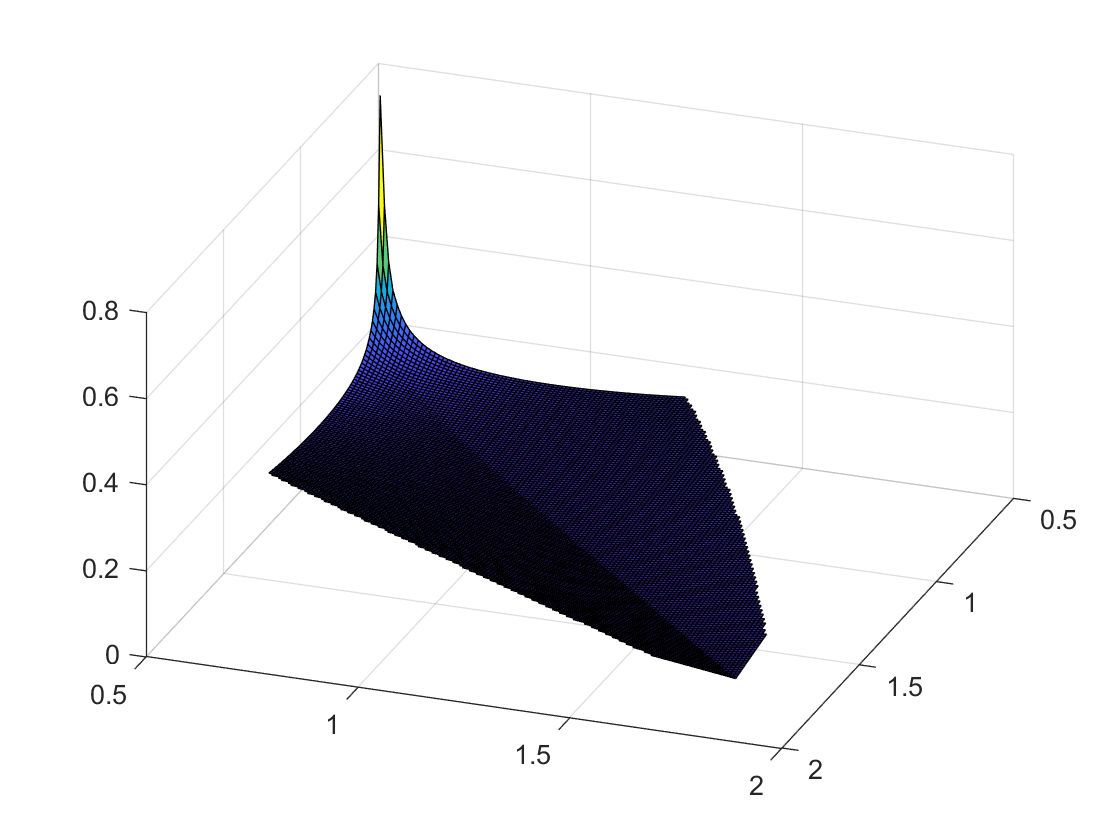

T = funcs.pulleyTorque(max(f.F21,f.F22));
surf(l1_list,l2_list,T)

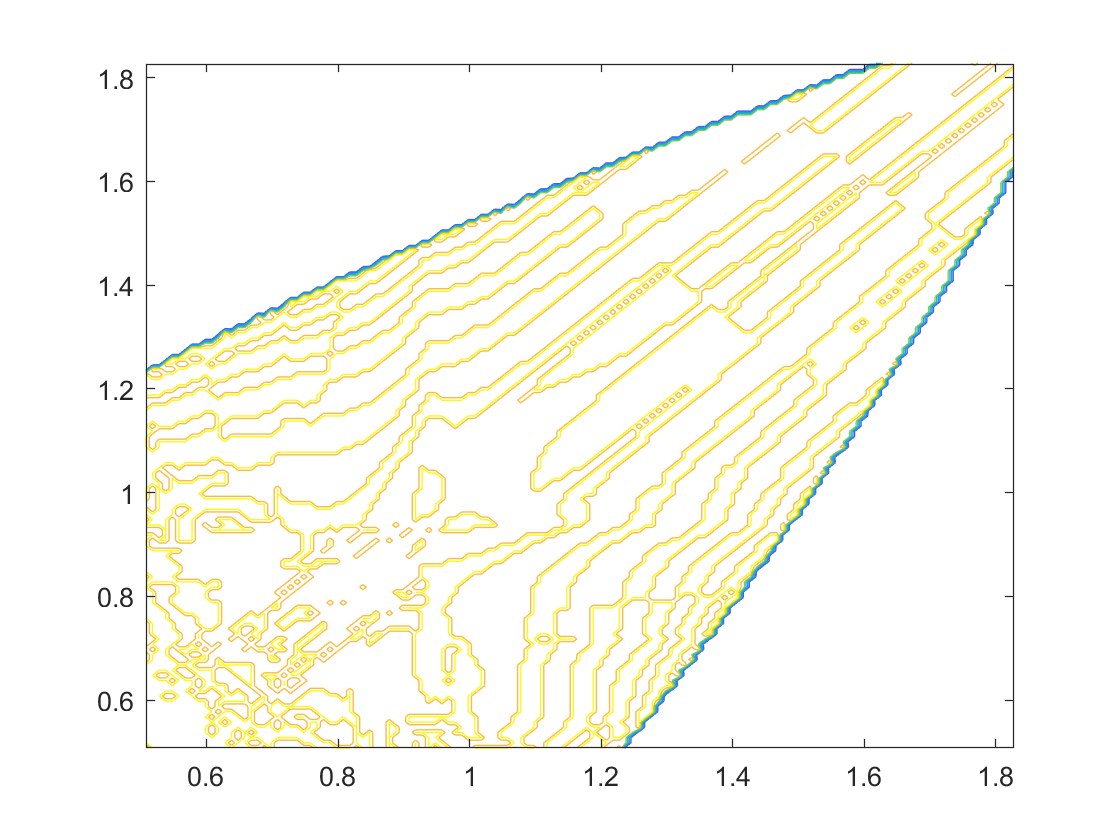

contour(l1_list,l2_list,exitflags)

save("fwdKineResults.mat", "x", "f", "T", "exitflags")